%1c and 1d
syms C s L Vi c1 R
A=[0 0 1 -1 -1;
    1 0 0 0 -R/c1;
    1 0 0 -R 0;
    C*s -C*s 1 0 0;
    0 1 L*s 0 0]

$$A = \left(\begin{array}{ccccc} 0 & 0 & 1 & -1 & -1\\ 1 & 0 & 0 & 0 & -\frac{R}{c_{1}}\\ 1 & 0 & 0 & -R & 0\\ C\,s & -C\,s & 1 & 0 & 0\\ 0 & 1 & L\,s & 0 & 0 \end{array}\right)$$

b=[0 0 0 0 Vi]'

$$b = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ \bar{\mathrm{Vi}} \end{array}\right)$$

x=A\b

$$x = \begin{array}{l} \left(\begin{array}{c} \frac{C\,R\,s\,\bar{\mathrm{Vi}}}{\sigma_{1}}\\ \frac{\bar{\mathrm{Vi}}+c_{1}\,\bar{\mathrm{Vi}}+C\,R\,s\,\bar{\mathrm{Vi}}}{\sigma_{1}}\\ \frac{C\,s\,\bar{\mathrm{Vi}}+C\,c_{1}\,s\,\bar{\mathrm{Vi}}}{\sigma_{1}}\\ \frac{C\,s\,\bar{\mathrm{Vi}}}{\sigma_{1}}\\ \frac{C\,c_{1}\,s\,\bar{\mathrm{Vi}}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=c_{1}+C\,R\,s+C\,L\,s^{2}+C\,L\,c_{1}\,s^{2}+1 \end{array}$$

Vo_LPF1=simplify(x(1))

$$Vo\_LPF1 = \frac{C\,R\,s\,\bar{\mathrm{Vi}}}{c_{1}+C\,R\,s+C\,L\,s^{2}+C\,L\,c_{1}\,s^{2}+1}$$

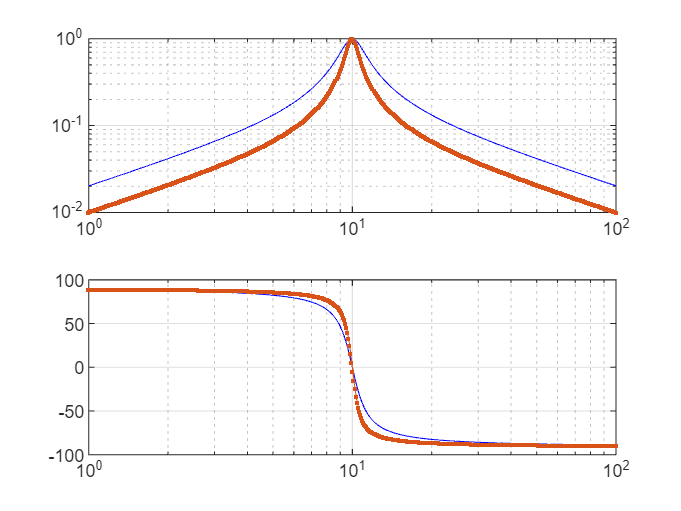

omega1=10; q=5; F_LPF1=RR_tf([omega1/q 0],[1 omega1/q omega1^2]);
omega1=10; q=10; F_LPF2=RR_tf([omega1/q 0],[1 omega1/q omega1^2]);
figure(1), RR_bode(F_LPF1)
figure(1), RR_bode(F_LPF2,g)